% Author: Kenneth H.L. Ho
% Copyright 2019 RIKEN BDR
% License: GPL v3 https://www.gnu.org/licenses/gpl-3.0.txt 

## Access image directly from SSBD database into MATLAB

% uses ssbdapi class defined in ssbdapi.m 
% using variable q to access ssbdapi class.
q = ssbdapi;

% Access SSBD and retrieve image id = 1, Z = 30, t = 0
k_img = q.image(1, 30, 0); 

id: 1, z: 30, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/1/30/0


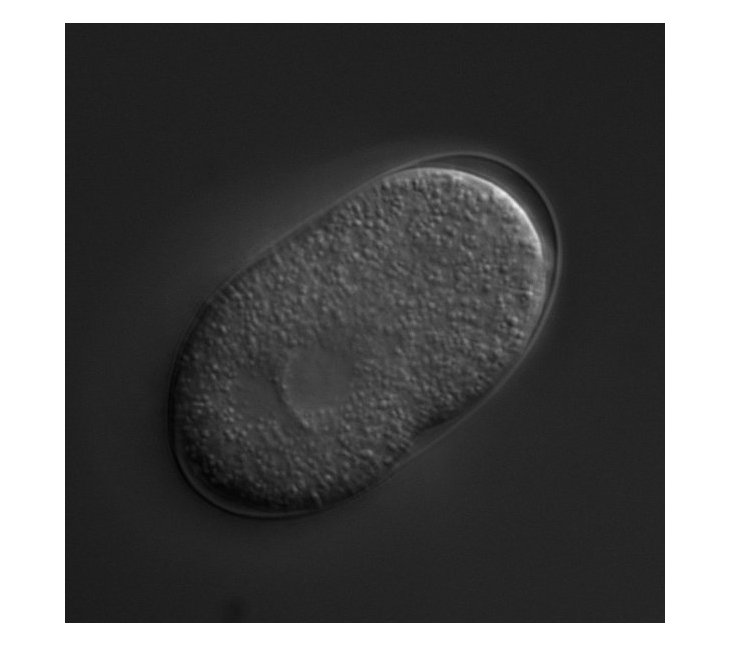

imshow(k_img)

% Accessing quantitative data from the SSBD database
% ssbd.bd5coords(bdml_id, time, offset, limit)
%
% here we access the data with bdmlID =4ed09fa3-7650-45a9-ac55-426980aa7d0a,ts=0, 

coords = q.bd5coords('bdmlID', '4ed09fa3-7650-45a9-ac55-426980aa7d0a', 'ts', 0, 'offset', 0, 'limit', 20)

bdmlID=4ed09fa3-7650-45a9-ac55-426980aa7d0a, ts=0, offset=0, limit=20
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=4ed09fa3-7650-45a9-ac55-426980aa7d0a&ts=0&offset=0&limit=20



coords = struct with fields:
       meta: [1×1 struct]
    objects: [20×1 struct]


% It returns two structures, meta and objects 
disp(coords.meta)

          limit: 20
           next: '/SSBD/api/v3/bd5coords/?bdmlID=4ed09fa3-7650-45a9-ac55-426980aa7d0a&format=json&limit=20&ts=0&offset=20'
         offset: 0
       previous: []
    total_count: 9691



% display the 2nd element of objects
coords.objects(2)

ans = struct with fields:
    entity: 'line'
        id: '1000'
     label: 'P0'
    radius: []
       sid: 0
         t: '1'
         x: '193'
         y: '351'
         z: '11'


% display objects - a structure.
disp(coords.objects)

  20×1 struct array with fields:

    entity
    id
    label
    radius
    sid
    t
    x
    y
    z



% display x coordinates within the objects
coords.objects.x

ans = '194'

ans = '193'

ans = '193'

ans = '192'

ans = '192'

ans = '192'

ans = '191'

ans = '190'

ans = '189'

ans = '188'

ans = '187'

ans = '186'

ans = '185'

ans = '184'

ans = '183'

ans = '182'

ans = '181'

ans = '180'

ans = '179'

ans = '179'

% display x coordinates within the objects

coords.objects.y

ans = '350'

ans = '351'

ans = '352'

ans = '353'

ans = '354'

ans = '355'

ans = '356'

ans = '356'

ans = '356'

ans = '356'

ans = '356'

ans = '356'

ans = '356'

ans = '356'

ans = '355'

ans = '355'

ans = '355'

ans = '355'

ans = '356'

ans = '357'

% display the x coordinates of the 2nd element of objects
coords.objects(2).x

ans = '193'

% finding the size of objects
size(coords.objects)

ans =     20     1


% find the scaling factor of the dataset given the bdmlID = "4ed09fa3-7650-45a9-ac55-426980aa7d0a"
scale = q.bd5scaleunit("4ed09fa3-7650-45a9-ac55-426980aa7d0a")

bdmlID=4ed09fa3-7650-45a9-ac55-426980aa7d0a
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5scaleunit/?format=json&bdmlID=4ed09fa3-7650-45a9-ac55-426980aa7d0a&offset=0&limit=1



scale = struct with fields:
       meta: [1×1 struct]
    objects: [1×1 struct]


% scale returns 2 structure, meta and objects
% showing meta structure of scale. 
% this does not normally contain useful information.
scale.meta

ans = struct with fields:
          limit: 1
           next: []
         offset: 0
       previous: []
    total_count: 1


% scale objects return the scaling factors of the dataset
scale.objects

ans = struct with fields:
    dimension: '3D+T'
        sUnit: 'micrometer'
       tScale: '40'
        tUnit: 'second'
       xScale: '0.105'
       yScale: '0.105'
       zScale: '0.5'


% scaling factor for of x 
scale.objects.xScale

ans = '0.105'

## Analysis - plotting proliferation curve of *C. elegans* by counting the number of nucleus

bdmlid = '800faa21-c28c-4b72-bd12-d41f2eed02e8';
ts = 0; % time seris n
offset = 0;
limit = 1;
no_of_nucleus = [];
tsi = []; % time series index
resultdata = q.bd5coords('bdmlID', bdmlid, 'ts', ts, 'offset', offset, 'limit', limit)

bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=0, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=0&offset=0&limit=1



resultdata = struct with fields:
       meta: [1×1 struct]
    objects: [1×1 struct]


disp(["ts=" ts]);

    "ts="    "0"



% display the total number of objects
disp(resultdata.meta.total_count);

     5



% if the number of nucleus is more than zero, request the next time series index ts
% and retrieve the number of nucleus (nn) at each ts 
% put all the rsults in the array no_of_nucleus and 

nn = resultdata.meta.total_count;
while nn > 0
    no_of_nucleus = [no_of_nucleus nn];
    tsi = [tsi ts]; % advances ts by 1.
    ts=ts+1;
    try
        resultdata = q.bd5coords('bdmlID', bdmlid, 'ts', ts, 'offset', offset, 'limit', limit);
        disp(["ts=" ts "nn=" nn]);
        nn = resultdata.meta.total_count;
    catch
        disp("finished")
        nn = -1;
    end
end

bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=1, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=1&offset=0&limit=1



    "ts="    "1"    "nn="    "5"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=2, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=2&offset=0&limit=1



    "ts="    "2"    "nn="    "5"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=3, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=3&offset=0&limit=1



    "ts="    "3"    "nn="    "5"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=4, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=4&offset=0&limit=1



    "ts="    "4"    "nn="    "5"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=5, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=5&offset=0&limit=1



    "ts="    "5"    "nn="    "7"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=6, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=6&offset=0&limit=1



    "ts="    "6"    "nn="    "7"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=7, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=7&offset=0&limit=1



    "ts="    "7"    "nn="    "7"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=8, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=8&offset=0&limit=1



    "ts="    "8"    "nn="    "8"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=9, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=9&offset=0&limit=1



    "ts="    "9"    "nn="    "8"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=10, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=10&offset=0&limit=1



    "ts="    "10"    "nn="    "8"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=11, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=11&offset=0&limit=1



    "ts="    "11"    "nn="    "8"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=12, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=12&offset=0&limit=1



    "ts="    "12"    "nn="    "9"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=13, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=13&offset=0&limit=1



    "ts="    "13"    "nn="    "9"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=14, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=14&offset=0&limit=1



    "ts="    "14"    "nn="    "9"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=15, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=15&offset=0&limit=1



    "ts="    "15"    "nn="    "9"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=16, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=16&offset=0&limit=1



    "ts="    "16"    "nn="    "9"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=17, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=17&offset=0&limit=1



    "ts="    "17"    "nn="    "9"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=18, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=18&offset=0&limit=1



    "ts="    "18"    "nn="    "9"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=19, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=19&offset=0&limit=1



    "ts="    "19"    "nn="    "11"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=20, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=20&offset=0&limit=1



    "ts="    "20"    "nn="    "13"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=21, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=21&offset=0&limit=1



    "ts="    "21"    "nn="    "13"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=22, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=22&offset=0&limit=1



    "ts="    "22"    "nn="    "13"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=23, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=23&offset=0&limit=1



    "ts="    "23"    "nn="    "13"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=24, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=24&offset=0&limit=1



    "ts="    "24"    "nn="    "13"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=25, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=25&offset=0&limit=1



    "ts="    "25"    "nn="    "14"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=26, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=26&offset=0&limit=1



    "ts="    "26"    "nn="    "15"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=27, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=27&offset=0&limit=1



    "ts="    "27"    "nn="    "15"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=28, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=28&offset=0&limit=1



    "ts="    "28"    "nn="    "15"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=29, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=29&offset=0&limit=1



    "ts="    "29"    "nn="    "15"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=30, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=30&offset=0&limit=1



    "ts="    "30"    "nn="    "16"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=31, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=31&offset=0&limit=1



    "ts="    "31"    "nn="    "16"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=32, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=32&offset=0&limit=1



    "ts="    "32"    "nn="    "16"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=33, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=33&offset=0&limit=1



    "ts="    "33"    "nn="    "16"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=34, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=34&offset=0&limit=1



    "ts="    "34"    "nn="    "16"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=35, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=35&offset=0&limit=1



    "ts="    "35"    "nn="    "16"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=36, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=36&offset=0&limit=1



    "ts="    "36"    "nn="    "25"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=37, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=37&offset=0&limit=1



    "ts="    "37"    "nn="    "25"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=38, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=38&offset=0&limit=1



    "ts="    "38"    "nn="    "25"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=39, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=39&offset=0&limit=1



    "ts="    "39"    "nn="    "25"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=40, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=40&offset=0&limit=1



    "ts="    "40"    "nn="    "25"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=41, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=41&offset=0&limit=1



    "ts="    "41"    "nn="    "25"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=42, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=42&offset=0&limit=1



    "ts="    "42"    "nn="    "25"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=43, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=43&offset=0&limit=1



    "ts="    "43"    "nn="    "25"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=44, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=44&offset=0&limit=1



    "ts="    "44"    "nn="    "25"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=45, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=45&offset=0&limit=1



    "ts="    "45"    "nn="    "25"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=46, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=46&offset=0&limit=1



    "ts="    "46"    "nn="    "27"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=47, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=47&offset=0&limit=1



    "ts="    "47"    "nn="    "27"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=48, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=48&offset=0&limit=1



    "ts="    "48"    "nn="    "27"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=49, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=49&offset=0&limit=1



    "ts="    "49"    "nn="    "27"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=50, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=50&offset=0&limit=1



    "ts="    "50"    "nn="    "27"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=51, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=51&offset=0&limit=1



    "ts="    "51"    "nn="    "27"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=52, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=52&offset=0&limit=1



    "ts="    "52"    "nn="    "27"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=53, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=53&offset=0&limit=1



    "ts="    "53"    "nn="    "29"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=54, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=54&offset=0&limit=1



    "ts="    "54"    "nn="    "29"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=55, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=55&offset=0&limit=1



    "ts="    "55"    "nn="    "29"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=56, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=56&offset=0&limit=1



    "ts="    "56"    "nn="    "29"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=57, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=57&offset=0&limit=1



    "ts="    "57"    "nn="    "29"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=58, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=58&offset=0&limit=1



    "ts="    "58"    "nn="    "29"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=59, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=59&offset=0&limit=1



    "ts="    "59"    "nn="    "31"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=60, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=60&offset=0&limit=1



    "ts="    "60"    "nn="    "38"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=61, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=61&offset=0&limit=1



    "ts="    "61"    "nn="    "44"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=62, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=62&offset=0&limit=1



    "ts="    "62"    "nn="    "46"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=63, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=63&offset=0&limit=1



    "ts="    "63"    "nn="    "46"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=64, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=64&offset=0&limit=1



    "ts="    "64"    "nn="    "46"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=65, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=65&offset=0&limit=1



    "ts="    "65"    "nn="    "47"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=66, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=66&offset=0&limit=1



    "ts="    "66"    "nn="    "47"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=67, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=67&offset=0&limit=1



    "ts="    "67"    "nn="    "48"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=68, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=68&offset=0&limit=1



    "ts="    "68"    "nn="    "48"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=69, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=69&offset=0&limit=1



    "ts="    "69"    "nn="    "49"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=70, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=70&offset=0&limit=1



    "ts="    "70"    "nn="    "50"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=71, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=71&offset=0&limit=1



    "ts="    "71"    "nn="    "51"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=72, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=72&offset=0&limit=1



    "ts="    "72"    "nn="    "52"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=73, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=73&offset=0&limit=1



    "ts="    "73"    "nn="    "52"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=74, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=74&offset=0&limit=1



    "ts="    "74"    "nn="    "52"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=75, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=75&offset=0&limit=1



    "ts="    "75"    "nn="    "52"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=76, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=76&offset=0&limit=1



    "ts="    "76"    "nn="    "52"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=77, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=77&offset=0&limit=1



    "ts="    "77"    "nn="    "52"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=78, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=78&offset=0&limit=1



    "ts="    "78"    "nn="    "52"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=79, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=79&offset=0&limit=1



    "ts="    "79"    "nn="    "52"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=80, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=80&offset=0&limit=1



    "ts="    "80"    "nn="    "52"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=81, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=81&offset=0&limit=1



    "ts="    "81"    "nn="    "54"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=82, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=82&offset=0&limit=1



    "ts="    "82"    "nn="    "54"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=83, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=83&offset=0&limit=1



    "ts="    "83"    "nn="    "55"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=84, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=84&offset=0&limit=1



    "ts="    "84"    "nn="    "55"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=85, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=85&offset=0&limit=1



    "ts="    "85"    "nn="    "56"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=86, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=86&offset=0&limit=1



    "ts="    "86"    "nn="    "61"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=87, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=87&offset=0&limit=1



    "ts="    "87"    "nn="    "68"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=88, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=88&offset=0&limit=1



    "ts="    "88"    "nn="    "78"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=89, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=89&offset=0&limit=1



    "ts="    "89"    "nn="    "83"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=90, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=90&offset=0&limit=1



    "ts="    "90"    "nn="    "88"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=91, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=91&offset=0&limit=1



    "ts="    "91"    "nn="    "89"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=92, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=92&offset=0&limit=1



    "ts="    "92"    "nn="    "89"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=93, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=93&offset=0&limit=1



    "ts="    "93"    "nn="    "89"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=94, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=94&offset=0&limit=1



    "ts="    "94"    "nn="    "89"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=95, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=95&offset=0&limit=1



    "ts="    "95"    "nn="    "89"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=96, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=96&offset=0&limit=1



    "ts="    "96"    "nn="    "89"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=97, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=97&offset=0&limit=1



    "ts="    "97"    "nn="    "89"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=98, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=98&offset=0&limit=1



    "ts="    "98"    "nn="    "91"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=99, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=99&offset=0&limit=1



    "ts="    "99"    "nn="    "93"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=100, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=100&offset=0&limit=1



    "ts="    "100"    "nn="    "94"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=101, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=101&offset=0&limit=1



    "ts="    "101"    "nn="    "94"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=102, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=102&offset=0&limit=1



    "ts="    "102"    "nn="    "96"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=103, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=103&offset=0&limit=1



    "ts="    "103"    "nn="    "97"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=104, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=104&offset=0&limit=1



    "ts="    "104"    "nn="    "98"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=105, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=105&offset=0&limit=1



    "ts="    "105"    "nn="    "98"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=106, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=106&offset=0&limit=1



    "ts="    "106"    "nn="    "99"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=107, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=107&offset=0&limit=1



    "ts="    "107"    "nn="    "101"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=108, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=108&offset=0&limit=1



    "ts="    "108"    "nn="    "101"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=109, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=109&offset=0&limit=1



    "ts="    "109"    "nn="    "102"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=110, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=110&offset=0&limit=1



    "ts="    "110"    "nn="    "103"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=111, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=111&offset=0&limit=1



    "ts="    "111"    "nn="    "103"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=112, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=112&offset=0&limit=1



    "ts="    "112"    "nn="    "104"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=113, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=113&offset=0&limit=1



    "ts="    "113"    "nn="    "105"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=114, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=114&offset=0&limit=1



    "ts="    "114"    "nn="    "106"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=115, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=115&offset=0&limit=1



    "ts="    "115"    "nn="    "106"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=116, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=116&offset=0&limit=1



    "ts="    "116"    "nn="    "107"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=117, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=117&offset=0&limit=1



    "ts="    "117"    "nn="    "107"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=118, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=118&offset=0&limit=1



    "ts="    "118"    "nn="    "109"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=119, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=119&offset=0&limit=1



    "ts="    "119"    "nn="    "112"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=120, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=120&offset=0&limit=1



    "ts="    "120"    "nn="    "117"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=121, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=121&offset=0&limit=1



    "ts="    "121"    "nn="    "128"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=122, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=122&offset=0&limit=1



    "ts="    "122"    "nn="    "140"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=123, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=123&offset=0&limit=1



    "ts="    "123"    "nn="    "146"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=124, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=124&offset=0&limit=1



    "ts="    "124"    "nn="    "152"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=125, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=125&offset=0&limit=1



    "ts="    "125"    "nn="    "158"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=126, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=126&offset=0&limit=1



    "ts="    "126"    "nn="    "162"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=127, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=127&offset=0&limit=1



    "ts="    "127"    "nn="    "164"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=128, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=128&offset=0&limit=1



    "ts="    "128"    "nn="    "169"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=129, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=129&offset=0&limit=1



    "ts="    "129"    "nn="    "169"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=130, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=130&offset=0&limit=1



    "ts="    "130"    "nn="    "175"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=131, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=131&offset=0&limit=1



    "ts="    "131"    "nn="    "177"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=132, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=132&offset=0&limit=1



    "ts="    "132"    "nn="    "179"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=133, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=133&offset=0&limit=1



    "ts="    "133"    "nn="    "180"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=134, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=134&offset=0&limit=1



    "ts="    "134"    "nn="    "181"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=135, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=135&offset=0&limit=1



    "ts="    "135"    "nn="    "181"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=136, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=136&offset=0&limit=1



    "ts="    "136"    "nn="    "182"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=137, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=137&offset=0&limit=1



    "ts="    "137"    "nn="    "183"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=138, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=138&offset=0&limit=1



    "ts="    "138"    "nn="    "184"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=139, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=139&offset=0&limit=1



    "ts="    "139"    "nn="    "186"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=140, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=140&offset=0&limit=1



    "ts="    "140"    "nn="    "187"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=141, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=141&offset=0&limit=1



    "ts="    "141"    "nn="    "187"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=142, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=142&offset=0&limit=1



    "ts="    "142"    "nn="    "187"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=143, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=143&offset=0&limit=1



    "ts="    "143"    "nn="    "187"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=144, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=144&offset=0&limit=1



    "ts="    "144"    "nn="    "188"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=145, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=145&offset=0&limit=1



    "ts="    "145"    "nn="    "188"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=146, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=146&offset=0&limit=1



    "ts="    "146"    "nn="    "189"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=147, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=147&offset=0&limit=1



    "ts="    "147"    "nn="    "191"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=148, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=148&offset=0&limit=1



    "ts="    "148"    "nn="    "192"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=149, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=149&offset=0&limit=1



    "ts="    "149"    "nn="    "193"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=150, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=150&offset=0&limit=1



    "ts="    "150"    "nn="    "193"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=151, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=151&offset=0&limit=1



    "ts="    "151"    "nn="    "193"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=152, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=152&offset=0&limit=1



    "ts="    "152"    "nn="    "193"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=153, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=153&offset=0&limit=1



    "ts="    "153"    "nn="    "194"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=154, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=154&offset=0&limit=1



    "ts="    "154"    "nn="    "194"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=155, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=155&offset=0&limit=1



    "ts="    "155"    "nn="    "196"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=156, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=156&offset=0&limit=1



    "ts="    "156"    "nn="    "198"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=157, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=157&offset=0&limit=1



    "ts="    "157"    "nn="    "201"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=158, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=158&offset=0&limit=1



    "ts="    "158"    "nn="    "201"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=159, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=159&offset=0&limit=1



    "ts="    "159"    "nn="    "202"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=160, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=160&offset=0&limit=1



    "ts="    "160"    "nn="    "206"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=161, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=161&offset=0&limit=1



    "ts="    "161"    "nn="    "207"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=162, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=162&offset=0&limit=1



    "ts="    "162"    "nn="    "212"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=163, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=163&offset=0&limit=1



    "ts="    "163"    "nn="    "216"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=164, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=164&offset=0&limit=1



    "ts="    "164"    "nn="    "228"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=165, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=165&offset=0&limit=1



    "ts="    "165"    "nn="    "233"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=166, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=166&offset=0&limit=1



    "ts="    "166"    "nn="    "241"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=167, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=167&offset=0&limit=1



    "ts="    "167"    "nn="    "257"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=168, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=168&offset=0&limit=1



    "ts="    "168"    "nn="    "269"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=169, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=169&offset=0&limit=1



    "ts="    "169"    "nn="    "279"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=170, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=170&offset=0&limit=1



    "ts="    "170"    "nn="    "288"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=171, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=171&offset=0&limit=1



    "ts="    "171"    "nn="    "300"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=172, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=172&offset=0&limit=1



    "ts="    "172"    "nn="    "307"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=173, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=173&offset=0&limit=1



    "ts="    "173"    "nn="    "317"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=174, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=174&offset=0&limit=1



    "ts="    "174"    "nn="    "318"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=175, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=175&offset=0&limit=1



    "ts="    "175"    "nn="    "325"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=176, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=176&offset=0&limit=1



    "ts="    "176"    "nn="    "330"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=177, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=177&offset=0&limit=1



    "ts="    "177"    "nn="    "335"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=178, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=178&offset=0&limit=1



    "ts="    "178"    "nn="    "341"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=179, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=179&offset=0&limit=1



    "ts="    "179"    "nn="    "342"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=180, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=180&offset=0&limit=1



    "ts="    "180"    "nn="    "346"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=181, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=181&offset=0&limit=1



    "ts="    "181"    "nn="    "348"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=182, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=182&offset=0&limit=1



    "ts="    "182"    "nn="    "350"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=183, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=183&offset=0&limit=1



    "ts="    "183"    "nn="    "352"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=184, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=184&offset=0&limit=1



    "ts="    "184"    "nn="    "356"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=185, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=185&offset=0&limit=1



    "ts="    "185"    "nn="    "356"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=186, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=186&offset=0&limit=1



    "ts="    "186"    "nn="    "357"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=187, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=187&offset=0&limit=1



    "ts="    "187"    "nn="    "359"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=188, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=188&offset=0&limit=1



    "ts="    "188"    "nn="    "359"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=189, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=189&offset=0&limit=1



    "ts="    "189"    "nn="    "359"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=190, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=190&offset=0&limit=1



    "ts="    "190"    "nn="    "359"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=191, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=191&offset=0&limit=1



    "ts="    "191"    "nn="    "360"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=192, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=192&offset=0&limit=1



    "ts="    "192"    "nn="    "360"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=193, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=193&offset=0&limit=1



    "ts="    "193"    "nn="    "362"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=194, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=194&offset=0&limit=1



    "ts="    "194"    "nn="    "362"



bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=195, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=195&offset=0&limit=1



finished


% disp(timept)

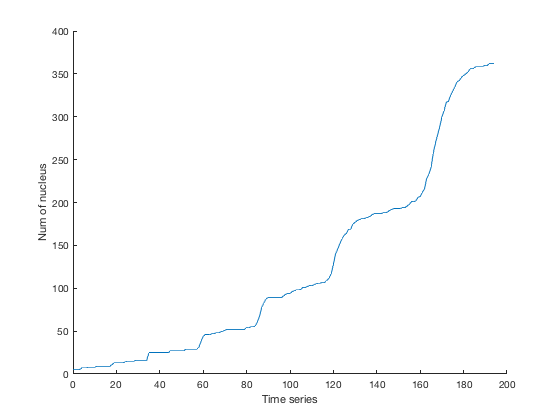

% Plot out the proliferation curve - namely the number of nucleaus over time.
figure;
hold on
plot(tsi, no_of_nucleus);
hold off;
xlabel('Time series')
ylabel('Num of nucleus')

% retrieve meta data from bdmlID = '800faa21-c28c-4b72-bd12-d41f2eed02e8'
resultdata = q.data('bdmlID', bdmlid)

    "offset:"    "0"    "limit:"    "20"

http://ssbd.qbic.riken.jp/SSBD/api/v3/data/?format=json&bdmlID__icontains=800faa21-c28c-4b72-bd12-d41f2eed02e8&offset=0&limit=20



resultdata = struct with fields:
       meta: [1×1 struct]
    objects: [1×1 struct]


% show the result 1 of objects
resultdata.objects(1)

ans = struct with fields:
              PMID: '16477039'
               SID: 1
           basedon: 'Experiment'
            bdmlID: '800faa21-c28c-4b72-bd12-d41f2eed02e8'
          citation: []
      contributors: 'Bao Zhirong, John Murray, Thomas Boyle, Siew Loon Ooi, Matthew Sandel, Robert Waterston'
          datatype: 'nuclear division dynamics'
            dblink: 'http://waterston.gs.washington.edu/StarryNite.html'
       description: 'quantitative information about nuclear division dynamics in wild-type embryo'
              gene: []
           license: 'CC BY-NC-SA'
           localID: '081505_L1'
    method_summary: 'See details in Bao et al. (2006) Proc Natl Acad Sci USA 103, 2707-2712.'
               orf: []
          organism: 'C. elegans'
           release: '2017-12-20'
        schema_ver: '3.000'
             title: 'BDML file for quantitative information about nuclear division dynamics of wild-type embryo'


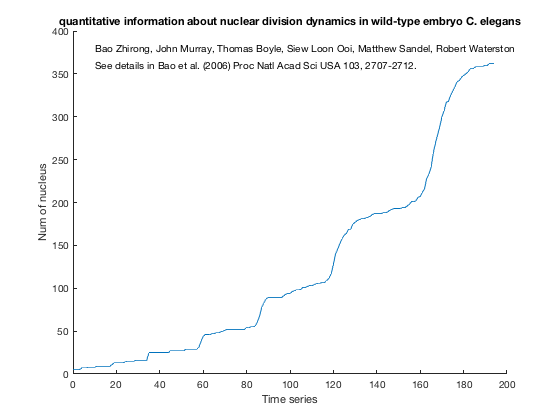

% Re-plot the curve with title, organism and contributors
figure;
hold on
plot(tsi, no_of_nucleus);
hold off;
xlabel('Time series');
ylabel('Num of nucleus');
title([resultdata.objects(1).description ' ' resultdata.objects(1).organism]); % putting a title based on description and organism
text(10, 380, resultdata.objects(1).contributors); % list out the contributors
text(10, 360, resultdata.objects(1).method_summary); % list out the reference

% Using ssbdapi.data to search for meta data - searching key basedon with value sim as in simulation 
resultdata = q.data('basedon','sim')

    "offset:"    "0"    "limit:"    "20"

http://ssbd.qbic.riken.jp/SSBD/api/v3/data/?format=json&basedon__icontains=sim&offset=0&limit=20



resultdata = struct with fields:
       meta: [1×1 struct]
    objects: [20×1 struct]


% Displaying 20th element in objects
resultdata.objects(20)

ans = struct with fields:
              PMID: '28256240'
               SID: 73
           basedon: 'Simulation'
            bdmlID: '925fce2c-7923-440e-8d0d-db4a5c55fabb'
          citation: []
      contributors: 'Masashi Fujii, Kaoru Ohashi, Yasuaki Karasawa, Minori Hikichi, Shinya Kuroda'
          datatype: 'molecular dynamics'
            dblink: []
       description: 'quantiative information about the simple stochastic model of Ca2+ increasing in the cell volume'
              gene: []
           license: 'CC BY-SA'
           localID: 'seed.45'
    method_summary: 'See details in Fujii et al. (2017) Biophys J., 112(4): 813-8286.'
               orf: []
          organism: []
           release: '2018-11-14'
        schema_ver: '3.000'
             title: 'BDML file for quantiative information about the simple stochastic model of Ca2+ increasing in the cell volume'


% searching for 'D. rerio' in the field 'organism'
resultdata = q.data('organism', 'D. rerio')

    "offset:"    "0"    "limit:"    "20"

http://ssbd.qbic.riken.jp/SSBD/api/v3/data/?format=json&organism__icontains=D. rerio&offset=0&limit=20



resultdata = struct with fields:
       meta: [1×1 struct]
    objects: [7×1 struct]


% Displaying all the result
for i=1:size(resultdata.objects)
    disp(resultdata.objects(i))
end

              PMID: '18845710'
               SID: 5
           basedon: 'Experiment'
            bdmlID: '320e02ee-1c6c-4e03-a6da-75b5c413b6a3'
          citation: []
      contributors: 'Philipp Keller, Annette Schmidt, Joachim Wittbrodt, Ernst Stelzer'
          datatype: 'nuclear positions'
            dblink: 'http://www.embl.de/digitalembryo/fish.html'
       description: 'in toto reconstruction of zebrafish MZoep mutant development'
              gene: []
           license: 'CC BY-NC-SA'
           localID: 'zebrafish_in_toto_mzoep.mat'
    method_summary: 'See details in Keller et al. (2008) Science 322, 1065-1069.'
               orf: []
          organism: 'D. rerio'
           release: '2017-12-20'
        schema_ver: '3.000'
             title: 'BDML file for in toto reconstruction of zebrafish MZoep mutant development'

              PMID: '18845710'
               SID: 5
           basedon: 'Experiment'
            bdmlID: 'bad5c56c-2a1d-4393-b1a5-ac9fd67c9999'
         

% searching for 'nucl' in the field 'title' - note: the default offset is 0 and limit is 20
resultdata = q.data('title', 'nuc');

    "offset:"    "0"    "limit:"    "20"

http://ssbd.qbic.riken.jp/SSBD/api/v3/data/?format=json&title__icontains=nuc&offset=0&limit=20



% Displaying all the result
for i=1:size(resultdata.objects)
    disp(resultdata.objects(i))
end

              PMID: '23172286'
               SID: 2
           basedon: 'Experiment'
            bdmlID: '7e0d3df0-573b-48d2-9e5a-7736f78e9e55'
          citation: []
      contributors: 'Koji Kyoda, Mari Furukawa, Ryoko Arai, Shuichi Onami'
          datatype: 'nuclear division dynamics'
            dblink: 'http://so.qbic.riken.jp/wddd/'
       description: 'quantitative information about nuclear division dynamics in wild-type embryo'
              gene: []
           license: 'CC BY-SA'
           localID: 'wt(N2)030127_01'
    method_summary: 'See details in Kyoda et al. (2013) Nucleic Acids Res 41, D732-D737.'
               orf: []
          organism: 'C. elegans'
           release: '2017-12-20'
        schema_ver: '3.000'
             title: 'BDML file for quantitative information about nuclear division dynamics of wild-type embryo'

              PMID: '23172286'
               SID: 2
           basedon: 'Experiment'
            bdmlID: '505c9e7b-2ffd-4073-8056-a308127b4822'


disp(resultdata.meta);

          limit: 20
           next: '/SSBD/api/v3/data/?title__icontains=nuc&format=json&limit=20&offset=20'
         offset: 0
       previous: []
    total_count: 208



% searching for 'nucl' in the field 'title' offset is 5 and limit is 25, i.e. fetch only 25 data items
resultdata = q.data('title', 'nuc','offset', 5, 'limit', 25)

    "offset:"    "5"    "limit:"    "25"

http://ssbd.qbic.riken.jp/SSBD/api/v3/data/?format=json&title__icontains=nuc&offset=5&limit=25



resultdata = struct with fields:
       meta: [1×1 struct]
    objects: [25×1 struct]


% Displaying all the result
for i=1:size(resultdata.objects)
    disp(resultdata.objects(i))
end

              PMID: '23172286'
               SID: 2
           basedon: 'Experiment'
            bdmlID: 'a719bdfd-2123-4862-83dd-6156a6932968'
          citation: []
      contributors: 'Koji Kyoda, Mari Furukawa, Ryoko Arai, Shuichi Onami'
          datatype: 'nuclear division dynamics'
            dblink: 'http://so.qbic.riken.jp/wddd/'
       description: 'quantitative information about nuclear division dynamics in C02F5.9(RNAi) embryo (pbs-6(RNAi) embryo)'
              gene: []
           license: 'CC BY-SA'
           localID: 'C02F5.9(gPCR)070607_03'
    method_summary: 'See details in Kyoda et al. (2013) Nucleic Acids Res 41, D732-D737.'
               orf: []
          organism: 'C. elegans'
           release: '2017-12-20'
        schema_ver: '3.000'
             title: 'BDML file for quantitative information about nuclear division dynamics of C02F5.9(RNAi) embryo'

              PMID: '23172286'
               SID: 2
           basedon: 'Experiment'
            bdmlID: '85

% searching for 'elegans' as in C. elegans in the field 'organism'
resultdata = q.data('organism', 'elegans')

    "offset:"    "0"    "limit:"    "20"

http://ssbd.qbic.riken.jp/SSBD/api/v3/data/?format=json&organism__icontains=elegans&offset=0&limit=20



resultdata = struct with fields:
       meta: [1×1 struct]
    objects: [20×1 struct]


% Displaying the result
for i=1:size(resultdata.objects)
    disp(resultdata.objects(i))
end

              PMID: '15698479'
               SID: 7
           basedon: 'Experiment'
            bdmlID: '6a8b0336-6144-470b-99d0-346f9daa9356'
          citation: []
      contributors: 'Christopher Cronin, Jane Mendel, Saleem Mukhtar, Young-Mee Kim, Robert Stirbl, Jehoshua Bruck, Paul Sternberg'
          datatype: 'behavior'
            dblink: 'http://www.its.caltech.edu/~cjc/wormdata.html'
       description: 'quantitative information about behavior of goa-1(sy192) worm in the presence of increasing concentrations of aldicarb'
              gene: []
           license: 'CC BY-NC-SA'
           localID: 'worm3_ald'
    method_summary: 'See details in Cronin et al. (2005) BMC Genetics 6, 5.'
               orf: []
          organism: 'C. elegans'
           release: '2017-12-20'
        schema_ver: '3.000'
             title: 'BDML file for quantitative information about behavior of goa-1(sy192) worm in the presence of increasing cocentrations of aldicarb'

              PMID: '231

% accessing the co-ordinates with bdmlID =4ed09fa3-7650-45a9-ac55-426980aa7d0a,ts=10,

no_of_nucleus = [];
timept = [];
resultdata = q.bd5coords('bdmlID','800faa21-c28c-4b72-bd12-d41f2eed02e8', 'ts', 10)

bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=10, offset=0, limit=20
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=10&offset=0&limit=20



resultdata = struct with fields:
       meta: [1×1 struct]
    objects: [8×1 struct]


% show the total number of data in bdmlID=4ed09fa3-7650-45a9-ac55-426980aa7d0a,ts=10

resultdata.meta.total_count

ans = 8

% show the result of x coordinates
resultdata.objects.x

ans = '366'

ans = '162'

ans = '533'

ans = '248'

ans = '438'

ans = '415'

ans = '326'

ans = '161'

% accessing the co-ordinates with bdmlID =4ed09fa3-7650-45a9-ac55-426980aa7d0a,ts=0,
% offset is 2 and limit is 2, i.e. 2 data items.

resultdata = q.bd5coords('bdmlID','800faa21-c28c-4b72-bd12-d41f2eed02e8', 'ts', 10, 'offset', 2, 'limit', 2)

bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8, ts=10, offset=2, limit=2
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=10&offset=2&limit=2



resultdata = struct with fields:
       meta: [1×1 struct]
    objects: [2×1 struct]


% show the total number of data in bdmlID=4ed09fa3-7650-45a9-ac55-426980aa7d0a,ts=0
resultdata.meta.total_count

ans = 8

% show the result of x coordinates

resultdata.objects.x

ans = '533'

ans = '248'